# Time series models and recursion

Control is commonly implemented in discrete time. In order to be able to analyse behaviour in discrete time the user needs some understanding of time series models, and indeed how these can be handled in MATLAB. 

One core requirement is to be able to simulate a discrete or time series model forward in time. This file focuses on looking at this from first principles, so using a loop to step forward in time one sample at a time.

In the long term, simulation time series/discrete models can be treated using Z-transforms which MATLAB handles formally using tools in the control toolbox.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical and mathematical background

- Using a loop to simulate

## 1. Technical and mathematical background

Time series models take the following form


$$y\left(k\right)+a\left(1\right)y\left(k-1\right)+a\left(2\right)y\left(k-2\right)+\cdots =b\left(1\right)u\left(k\right)+b\left(2\right)u\left(k-1\right)+\cdots$$


An equivalent z-transform model could be represented as:


$$\left(1+az^{-1} +a\left(2\right)z^{-2} +\cdots \right)y\left(k\right)=\left(b\left(1\right)z^{-1} +b\left(2\right)z^{-2} +\cdots \right)u\left(k\right)$$


This file shows how a simple recursion can be used to determine future values of the output, assuming the input values are known.

### **Example on paper**

Consider the model below with $u\left(k\right)=1,k>0\ldotp$


$$y\left(k\right)-1\ldotp 2y\left(k-1\right)+0\ldotp 8y\left(k-2\right)=1\ldotp 3u\left(k\right)+0\ldotp 4u\left(k-1\right)$$


Beginning from k=0 for simplicity, we can derive:


$$y\left(1\right)-1\ldotp 2y\left(0\right)+0\ldotp 8y\left(-1\right)=1\ldotp 3u\left(1\right)+0\ldotp 4u\left(-1\right)$$



$$y\left(2\right)-1\ldotp 2y\left(1\right)+0\ldotp 8y\left(0\right)=1\ldotp 3u\left(1\right)+0\ldotp 4u\left(0\right)$$



$$\begin{array}{l}
y\left(3\right)-1\ldotp 2y\left(2\right)+0\ldotp 8y\left(1\right)=1\ldotp 3u\left(2\right)+0\ldotp 4u\left(1\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\cdots 
\end{array}$$


## 2. Using a loop to simulate

The above recursion is easy to put into a loop with the minor caveat that MATLAB notation only uses positive integer indices for vectors, so we need a mapping from real sample time 'k', to the loop parameter.

For convenience the code below assumes the same number of 'a' and 'b' parameters and uses sample zero as the first computed value, so negative samples are in the past.

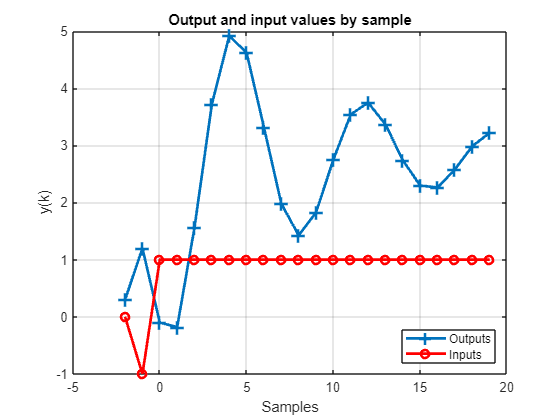

a=[1 -1.2 0.8]; % a parameters
b=[1.3 0.4];   % b parameters
na = length(a); % shift to allow for initial conditions
y = [0.3,1.2];   % initial conditions are [y(-2),y(-1)];
u = [0,-1];    % initial conditions are [u(-2),u(-1)]

% define future input values
runtime = 20;
u(na:na+runtime-1) = ones(1,runtime);

% use recursion to determine future outputs
for k=na:na+runtime-1
    y(k)= -y(k-1:-1:k-na+1)*a(2:end)' + u(k-1:-1:k-na+1)*b';
end

% Plotting
figure; clf
timevec = [1:runtime+na-1]-na;  % note shift from array index to time index
plot(timevec,y,'+-','markersize',10,'linewidth',2); hold on
plot(timevec,u,'ro-','markersize',6,'linewidth',2);
grid
xlabel('Samples');
title('Output and input values by sample')
ylabel('y(k)')
legend('Outputs','Inputs','Location','Southeast')